# Identificacion del sistema y diseño control

## Separar Datos en escalones

carpeta='E:\Mercury\control ROBOT\Escalones\';
archivos=dir(strcat(carpeta,'*.txt'));
datos=separarEscalones(archivos,carpeta);

## Verificar Datos

ver titulo para posteriormente elegir archivo a verificar

NumArchivo=3;
display(strcat(datos{NumArchivo}.title," ",datos{NumArchivo}.direccion," ",num2str(datos{NumArchivo}.voltaje)," ",datos{NumArchivo}.superficie));

    "datos_3_suelo_adelante_1060.txt adelante 1060 suelo"




s =
 
  s
 
Continuous-time transfer function.



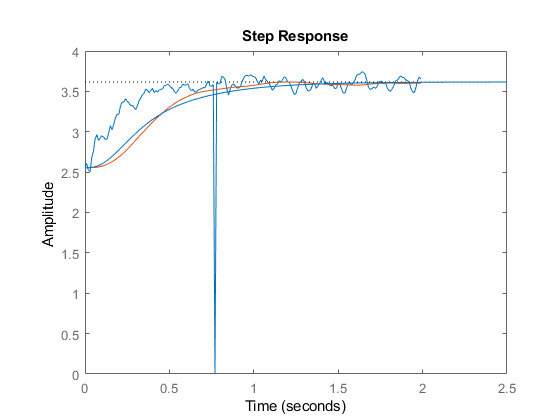

Numescalones=size(datos{NumArchivo}.datos);
Numescalones=Numescalones(3);
NumEscalon=3;
NumMotor=1;
if(NumEscalon>Numescalones)
display(strcat("El Maximo Numero de escalones es : ",num2str(Numescalones)));
else
tiempo=(0:199)*0.01;
velocidad=datos{NumArchivo}.datos(1:200,NumMotor+2,NumEscalon)/240;
plot(tiempo,velocidad);
hold on
velocidad=filtroVelocidad(velocidad,2,0.01);
plot(tiempo,velocidad);
maximo=max(velocidad);
minimo=min(velocidad);
syms s
s=tf('s')
Wc=4*pi;
Q=0.7;
step((maximo-minimo)*(2p.94/(s+2.94))*(Wc^2/(s^2+Wc/Q*s+Wc^2))+minimo)
hold off
%hold on
%voltaje=str2num(datos{NumArchivo}.voltaje)/100
%voltaje=voltaje*datos{NumArchivo}.datos(:,2,NumEscalon)/10000;
%plot(tiempo,voltaje);
%hold off
end

# Functions

function y=separarEscalones(archivos,carpeta)
    for i=1:length(archivos)
        datos=csvread(strcat(carpeta,archivos(i).name),2);
        title=archivos(i).name;
        Size=size(datos);
        cuenta=0;
        entrada=datos(1,2);
        rangos=[1 1];
        escalon=[];
        for j=1:length(datos)
            if(entrada ~= datos(j,2))
                entrada=datos(j,2);
                cuenta=cuenta+1;
                rangos(1)=rangos(2);
                rangos(2)=j;
                if(cuenta==1)
                    escalon(1:rangos(2)-rangos(1)+1,1:Size(2))=datos(rangos(1):rangos(2),:);
                else
                    escalon(1:rangos(2)-(rangos(1)-3)+1,1:Size(2),cuenta)=datos((rangos(1)-3):rangos(2),:);   
                end
            end
        end
        info_title=strsplit(title(1:length(title)-4),'_');
        a=struct;
        a.datos=escalon;
        a.title=title;
        a.direccion=cellstr(info_title(4));
        a.voltaje=cell2mat(info_title(5));
        a.superficie=cellstr(info_title(3));
        c(i,1)={a};
        
    end
    y=c;
end

function y=filtroVelocidad(velocidad,frecuencia,T)
    Q=0.7;
    Wc=2*pi*frecuencia;
    filtro=[0,velocidad(1),velocidad(1)];
    filtro1=ones(1,10).*velocidad(1:10);
    denominador=1+Wc*T/Q+Wc^2*T^2;
    velocidad1=velocidad;
    for i=1:length(velocidad)
        if( i>1 && velocidad1(i-1)-0.5>velocidad1(i))
            velocidad1(i)=velocidad1(i-1);
        end
        filtro(1)=filtro(2);
        filtro(2)=filtro(3);      
        filtro(3)= (Wc^2*T^2*velocidad1(i)-filtro(1)+filtro(2)*(2+Wc*T/Q))/denominador;
        if(i>6)
            filtro1(1:4)=filtro1(2:5);
            filtro1(5)=mean( [filtro1(1:5) filtro(3)] );
            velocidad2(i)=filtro1(5);
        else
            filtro1(i)=filtro(3);
            velocidad2(i)=filtro(3);
        end
    end
    y=velocidad2;
end